# Лабораторная работа №4

Решение СЛАУ МПИ.

n = 10;
eps = 1e-12;
 

Генерация матрицы размерности N с диагорнальным преобладанием.

A = gen_matr(n);
norm(A, 2)

ans = 993.9845

norm(A - eye(n), 2)

ans = 992.9845

XO = randi(100, n, 1);
B = A*XO;
[X, n] = simple_iter2(A, B, B, eps);
n

n = 9

norm(XO - X)

ans = 6.7741e-14

norm(A*X-B)

ans = 3.6209e-11

Зависимость количества итераций от погрешности:

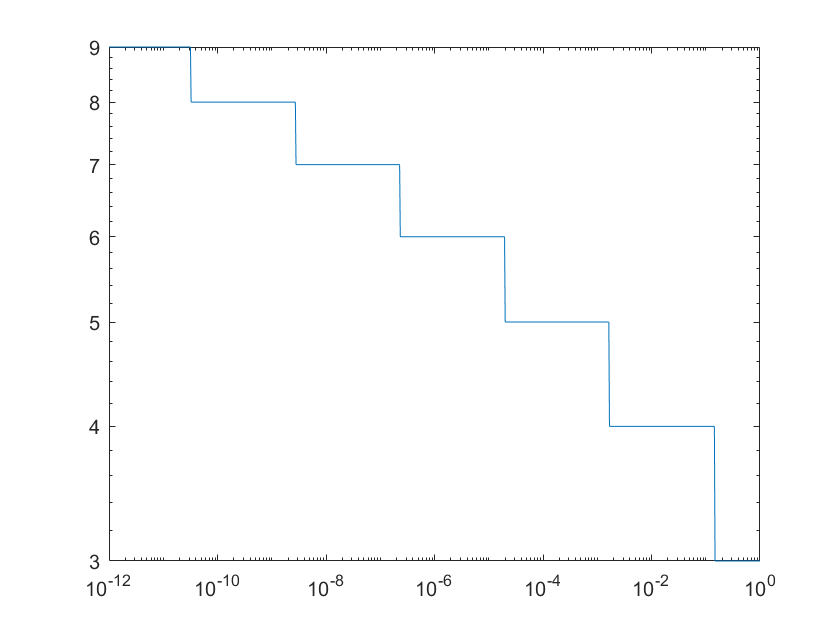

[E, N] = eps_cor(-12, 0, 10, 1000);
loglog(E, N);

Зависимость количества итераций от начального приближения

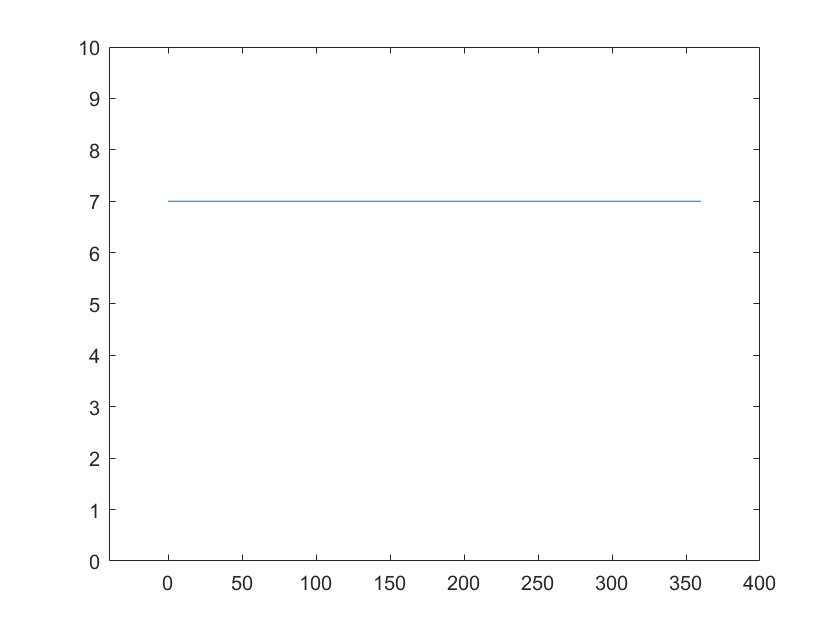

[NM, N] = norm_cor(1e-12, 10);
figure
plot(NM, N);
axis([-40 400 0 10])

Зависимость количества итераций при определителе -> 0.

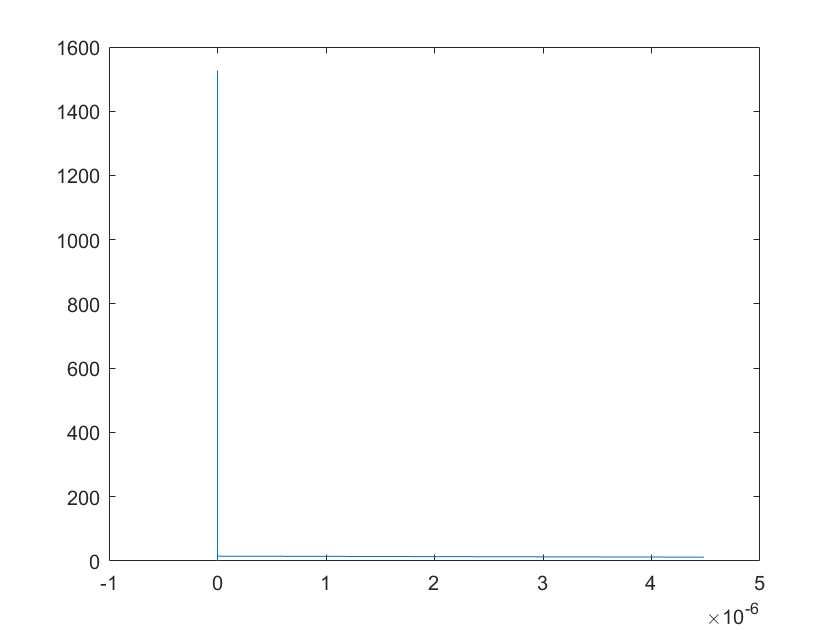

N = [];
DA = [];
for i = 1:100
    [X, n] = simple_iter2(A, B, B, eps);
    N(i) = n;
    DA(i) = det(A);
    A = reduce_det(A);
end
plot(DA(2:end), N(2:end));

function D = gen_matr(n)
    % '''Генерация матрицы с диагональным преобладанием'''
    V = [];
    for i = 1:n
        V(i) = randi([100 1000]);
    end
    D = rand(n);
    Dv = diag(V);
    D = D + Dv;
end

function [X0, n] = simple_iter(A, B, X0, eps)
    C = -(A - eye(size(A)));
    X = C*X0 + B;
    n = 0;
    while norm(X-X0) >= eps
        X0 = X;
        X = C*X0 + B;
        norm(X0-X, 2);
        n = n + 1;
    end
end

function [X0, n] = simple_iter2(A, B, X0, eps)
    sz = size(A);
    sz = sz(2);
    C = zeros(sz);
    D = diag(A);
    M = zeros(sz, 1);
    for i = 1:sz
        for j = 1:sz
            if i ~= j
              C(i, j) = -A(i, j)/D(i);
            end
            M(i) = B(i)/D(i);
        end
    end
    X = C*X0 + M;
    n = 0;
    while norm(X-X0) >= eps
        X0 = X;
        X = C*X0 + M;
        norm(X0-X, 2);
        n = n + 1;
    end
end

function [E, N] = eps_cor(eps_min, eps_max, n, np)
    E = logspace(eps_min, eps_max, np);
    A = gen_matr(n);
    XO = randi(100, n, 1);
    B = A*XO;
%     Xnp = randi([100 500], n, 1);
    Xnp = B;
    N = [];
    Sz = size(E);
    for i = 1:Sz(2)
        [X, n] = simple_iter2(A, B, Xnp, E(i));
        N = [N n];
    end
end

function [NN, N] = norm_cor(eps, n)
    angle = 0:0.01:360;
    A = gen_matr(n);
    XO = randi(100, n, 1);
    B = A*XO;
    XO = randi(100, n, 1);
    N = [];
    NN = [];
    Sz = size(angle);
    for i = 1:Sz(2)
        RM = gen_rot_matr(10, angle(i));
        [X, n] = simple_iter2(A, B, RM*XO, eps);
        N = [N n];
%         NN(i) = norm(XO - RM*XO, 2);
        NN(i) = angle(i);
    end
end

function M = gen_rot_matr(n, angle)
    M = eye(n);
    M(1, 1) = cosd(angle);
    M(2, 1) = sind(angle);
    M(1, 2) = -sind(angle);
    M(2, 2) = cosd(angle);
end

function A = reduce_det(A)
    A(1, 1) = A(1, 1)*10^(-4);
    A = A .* 10^(-3);
    A(1, 1) = A(1, 1)*10^3;
end